R=2

R = 2

L=0.5

L = 0.5000

K_e=0.1

K_e = 0.1000

K_t=0.1

K_t = 0.1000

J_m=0.01

J_m = 0.0100

J_L=0.02

J_L = 0.0200

b=0.001

b = 1.0000e-03

H=tf(K_t, [...
    (J_m+J_L)*L, ...
    R*(J_m+J_L)+b*L, ...
    b*R+K_e*K_t ...
]);
H


H =
 
              0.1
  ----------------------------
  0.015 s^2 + 0.0605 s + 0.012
 
Continuous-time transfer function.


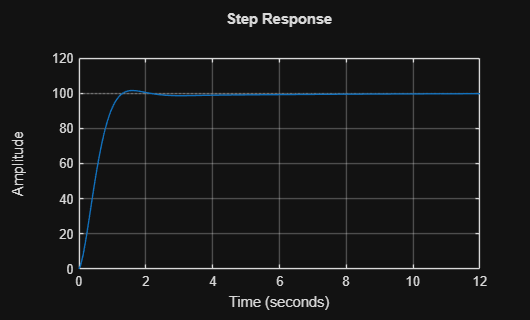

K_p = 1.2;
K_i = 0.2;
K_d = 0.05;
C = pid(K_p, K_i, K_d);
T = feedback(C*H, 1);

step(100*T)
grid on


stepinfo(100*T)

ans = struct with fields:
         RiseTime: 0.8153
    TransientTime: 1.1946
     SettlingTime: 1.1946
      SettlingMin: 90.3574
      SettlingMax: 101.4857
        Overshoot: 1.4857
       Undershoot: 0
             Peak: 101.4857
         PeakTime: 1.6000
